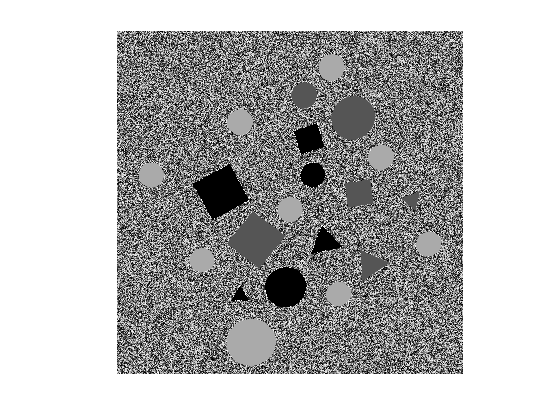

clear All; close all;

img = imread('test_01.png');
[H,S,V] = rgb2hsv(img);

figure();
imshow(H);

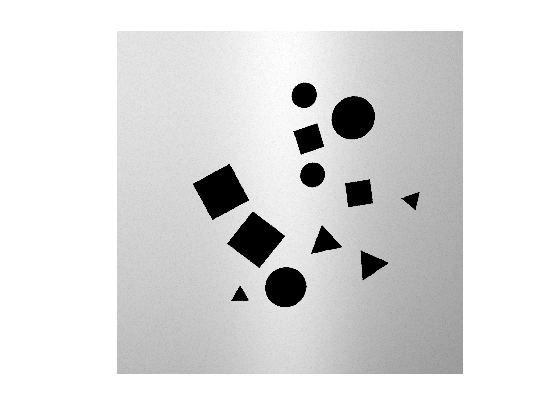


blue = img(:,:,3);
figure();
imshow(blue);

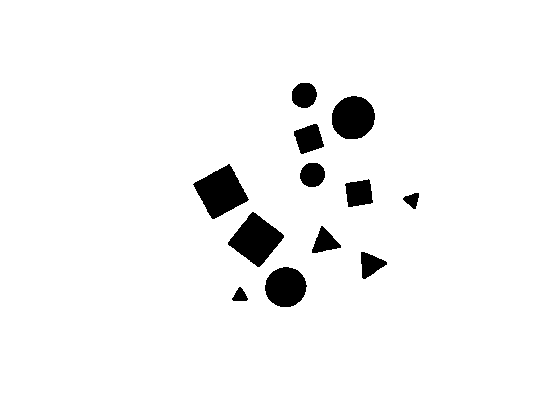



imgBin = imbinarize(blue,'adaptive','ForegroundPolarity','dark','Sensitivity',0.56);
imClose = imclose(imgBin,strel('disk',5)); 
figure();
imshow(imClose);

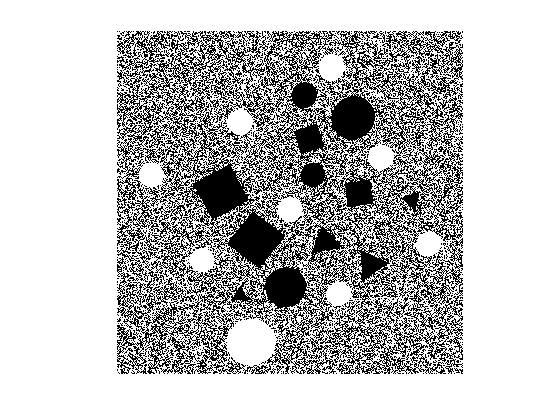


%
bin = imbinarize(H);
figure();
imshow(bin);